YMMH5=loadrobot("yaskawaMotomanMH5","DataFormat","row","Gravity",[0 0 -9.81])

YMMH5 =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link_s'  'link_l'  'link_u'  'link_r'  'link_b'  'link_t'}
      BaseName: 'base_link'
       Gravity: [0 0 -9.8100]
    DataFormat: 'row'


showdetails(YMMH5)

--------------------
Robot: (6 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        link_s        joint_s       revolute         base_link(0)   link_l(2)  
   2        link_l        joint_l       revolute            link_s(1)   link_u(3)  
   3        link_u        joint_u       revolute            link_l(2)   link_r(4)  
   4        link_r        joint_r       revolute            link_u(3)   link_b(5)  
   5        link_b        joint_b       revolute            link_r(4)   link_t(6)  
   6        link_t        joint_t       revolute            link_b(5)   
--------------------


angles=[30 40 -10 90 50 0]

angles =     30    40   -10    90    50     0


Roll=1.9546

Roll = 1.9546

Pitch=0.3754

Pitch = 0.3754

Yaw=0.2549

Yaw = 0.2549

X=-609.4/1000;
Y=-104.5/1000;
Z=-206.1/1000;
P=[X;Y;Z]

P =    -0.6094
   -0.1045
   -0.2061


RobotConfiguration=rt2tr(rpy2r(Roll,Pitch,Yaw),P)

RobotConfiguration =     0.9003   -0.2346    0.3666   -0.6094
    0.2346   -0.4481   -0.8627   -0.1045
    0.3667    0.8627   -0.3484   -0.2061
         0         0         0    1.0000


ik = inverseKinematics('RigidBodyTree',YMMH5);
ik.SolverParameters.AllowRandomRestart = false;
ik.SolverParameters.MaxTime=20;
weights = [1 1 1 1 1 1];
initialguess = YMMH5.homeConfiguration;
[configSoln,solnInfo] = ik('link_t',RobotConfiguration,weights,initialguess)

configSoln =     0.1761   -0.9816   -2.3736    0.0774    1.7581   -1.9684


solnInfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 0.7319
             ExitFlag: 1
               Status: 'best available'


configSolnd=rad2deg(configSoln)

configSolnd =    10.0894  -56.2406 -135.9973    4.4336  100.7288 -112.7793


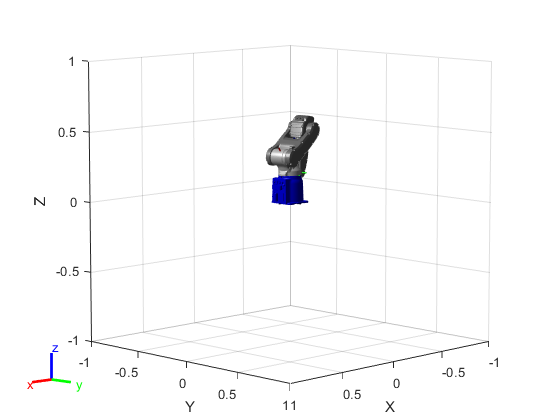

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties




show(YMMH5,configSoln)